# Actividad 1 En clase

Crear superficies

clear variables;
clf;
m = 10;
dm = .5; %entre mayor sea, más puntos y precisión se genera

% Definir los intérvalos de x

x = -m:dm:m;
y = -m:dm:m;
 

[xx , yy] = meshgrid(x,y);

[xx2 , yy2] = meshgrid(x,y);

[xx3 , yy3] = meshgrid(x,y);

fxy = xx.^2 +yy.^2;

fxy2 = xx2.^2 - yy2.^2;

fxy3 = (xx3.*sin(xx3) - yy3.*cos(yy3));


surf(xx,yy,fxy); %crea la superficie de la función
title 'Función 1: x^2 +y^2 ', 'FontSize', 30;

ans = 'FontSize'

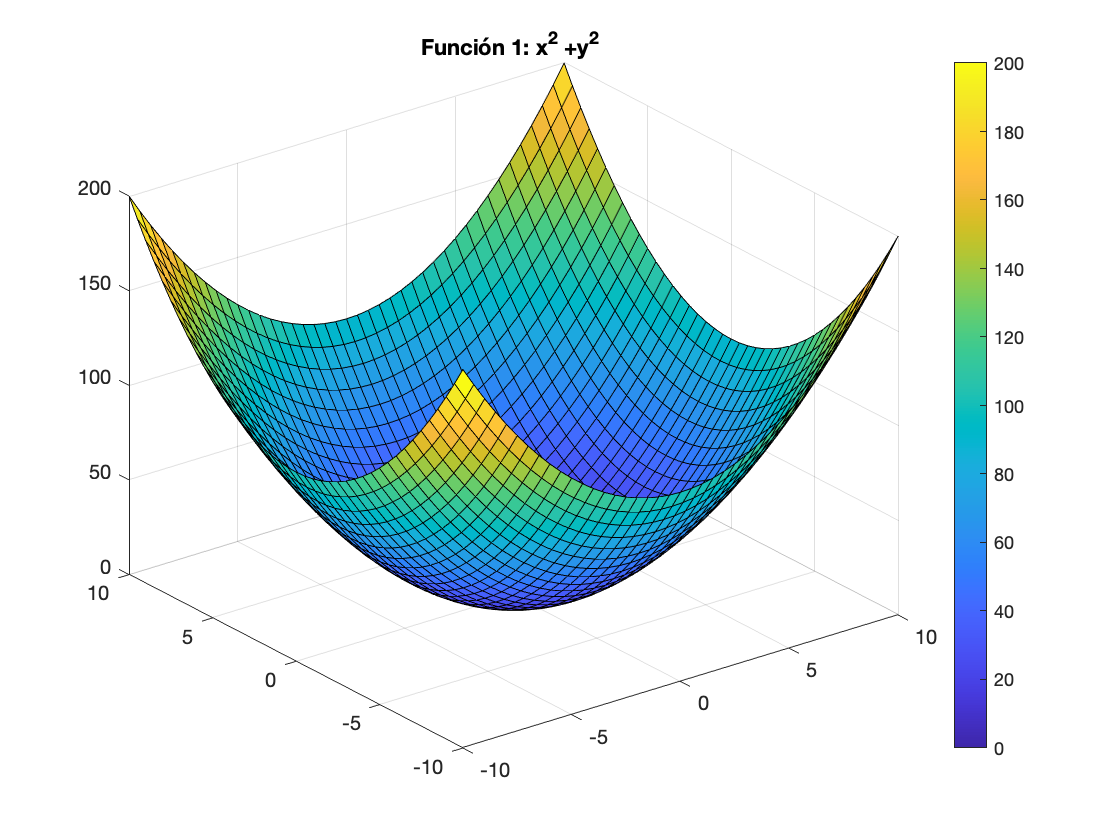

colorbar;



surf(xx2,yy2,fxy2);%crea la superficie de la función
title 'Función 1: x^2 - y^2 ', 'FontSize', 30;

ans = 'FontSize'

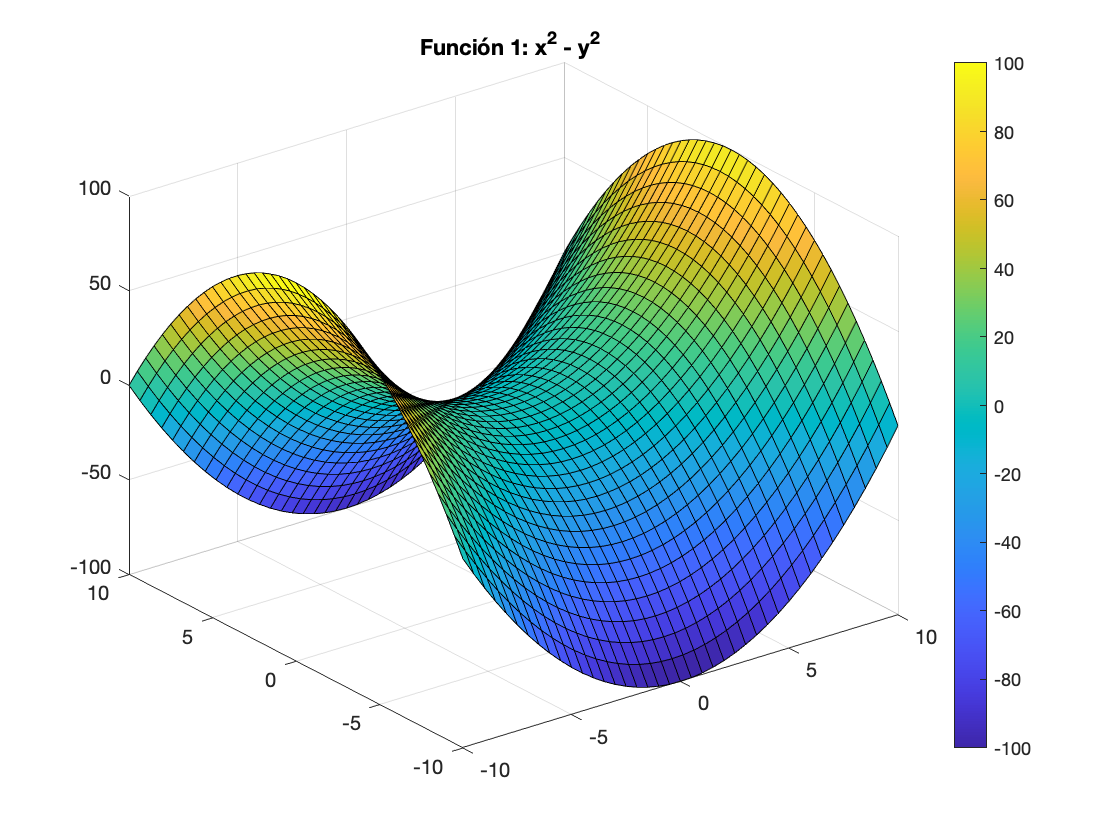

colorbar;



surf(xx3,yy3,fxy3);%crea la superficie de la función
title 'Función 1: (x*sin(x) - y*cos(y)) ', 'FontSize', 30;

ans = 'FontSize'

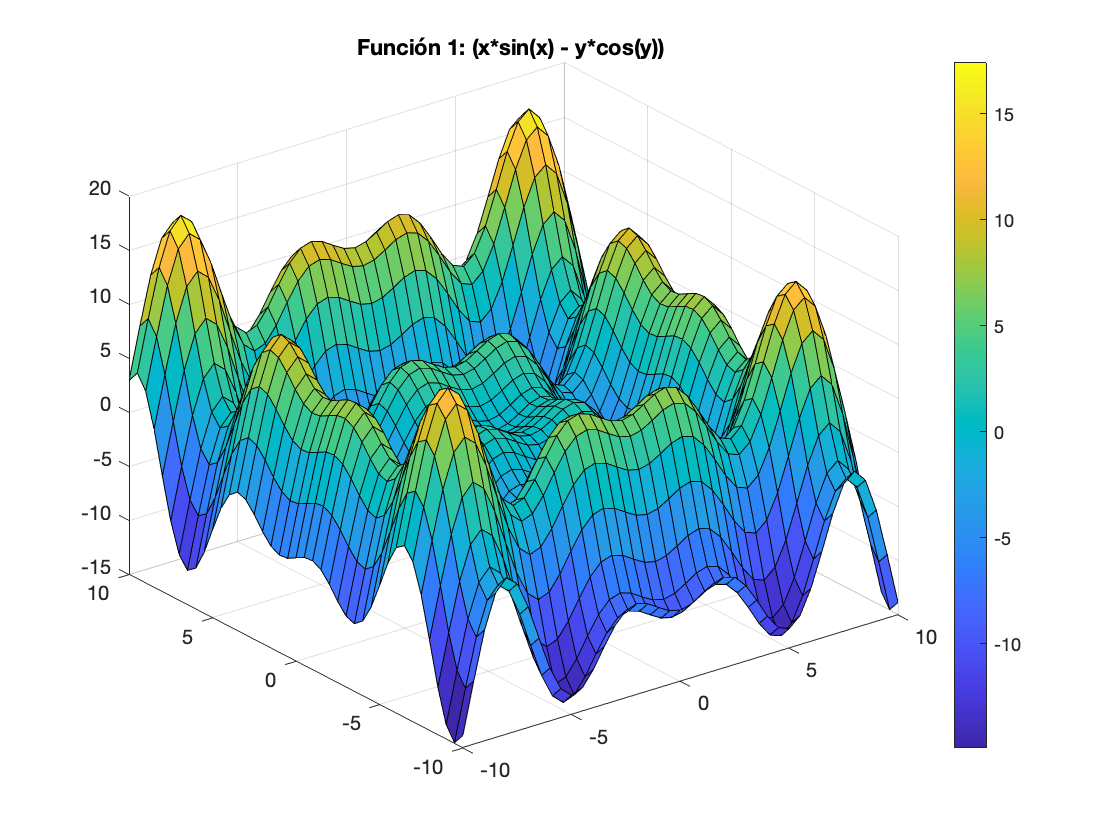


colorbar;

**Funcón de quiver en 2 dimesiones**

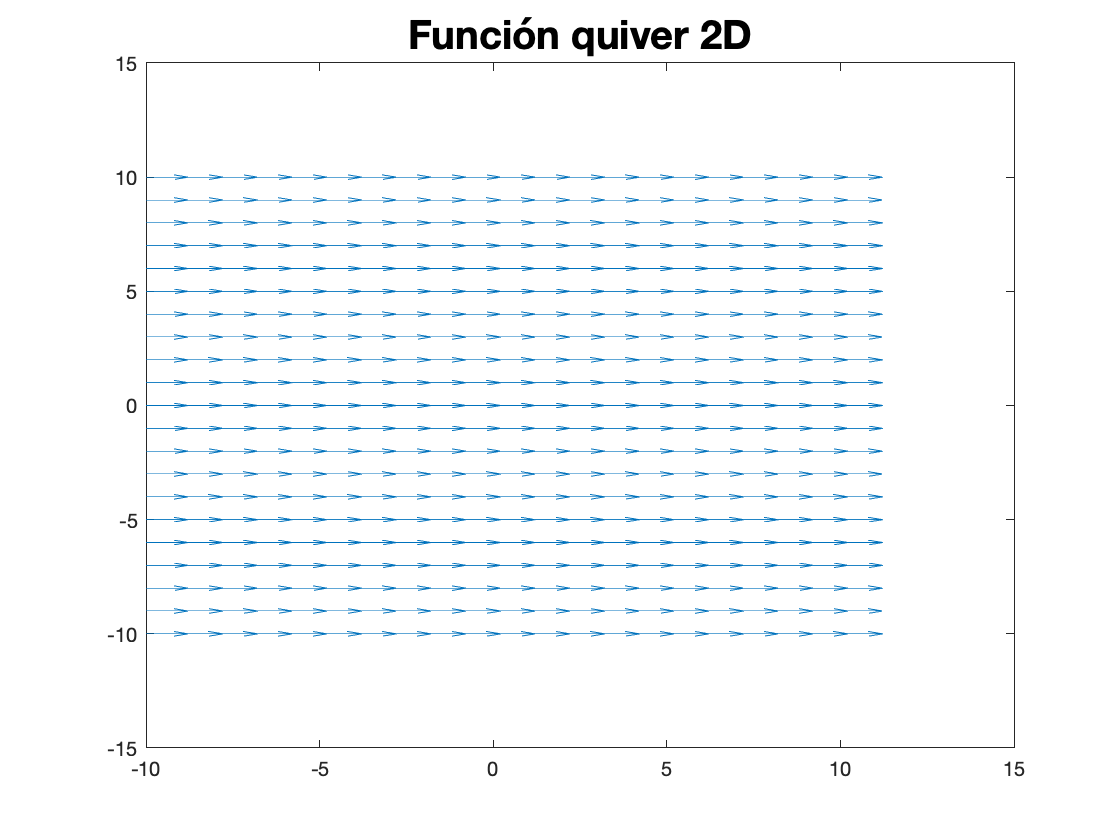

m1 = 10;
dm1 = 1; %entre mayor sea, más puntos y precisión se genera

% Definir los intérvalos de x

x2 = -m1:dm1:m1;
y2 = -m1:dm1:m1;
 

[xx , yy] = meshgrid(x2,y2);
Ex = ones(size(xx)); %dirección de las flechas en x, elegimos los valores de meshgrid para que se genere el vector uniforme 'xx'
Ey = zeros(size(yy)); %dirección de las flechas en y, elegimos los valores de meshgrid para que se genere el vector uniforme 'yy'
quiver(xx, yy, Ex, Ey);
title('Función quiver 2D', 'FontSize', 20);

**Función de quiver en 3 dimesiones**

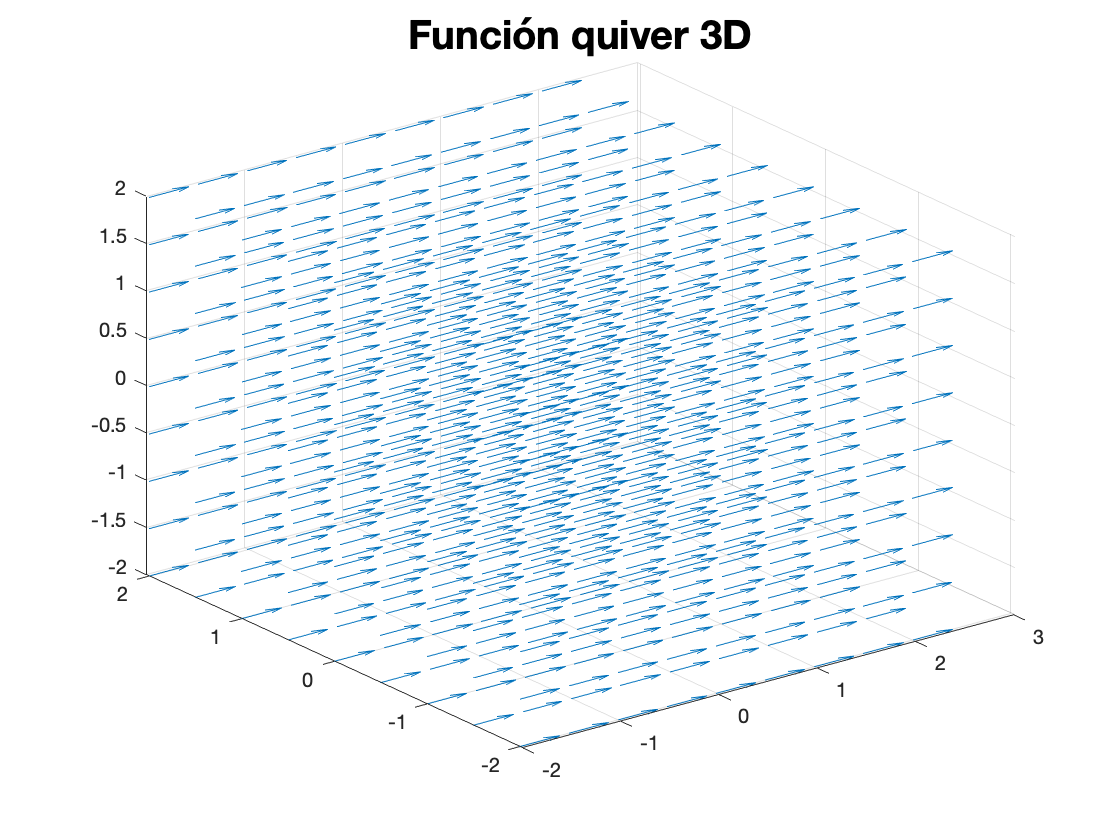

m2 = 2;
dm2 = .5; %entre mayor sea, más puntos y precisión se genera

% Definir los intérvalos de x

x2 = -m2:dm2:m2;
y2 = -m2:dm2:m2;
z2 = -m2:dm2:m2;
 

[xx , yy, zz] = meshgrid(x2, y2, z2);
Ex = ones(size(xx)); %dirección de las flechas en x, elegimos los valores de meshgrid para que se genere el vector uniforme 'xx'
Ey = zeros(size(yy)); %dirección de las flechas en y, elegimos los valores de meshgrid para que se genere el vector uniforme 'yy'
Ez = zeros(size(zz));
quiver3(xx, yy, zz, Ex, Ey, Ez);
title('Función quiver 3D', 'FontSize', 20);